% Masukkan nama file atau path gambar
image1_path = 'D:\TA\TA Kak chelli\Mask\BIRADS_2\bus_0191-r_mask.png';
%image2_path = 'D:\Git Repo\TA\Edge Sharpness\Profile intensity\hasil_zoom_384.png';
image2_path = 'D:\Git Repo\TA\Edge Sharpness\Profile intensity\hasil_zoom_384.png';

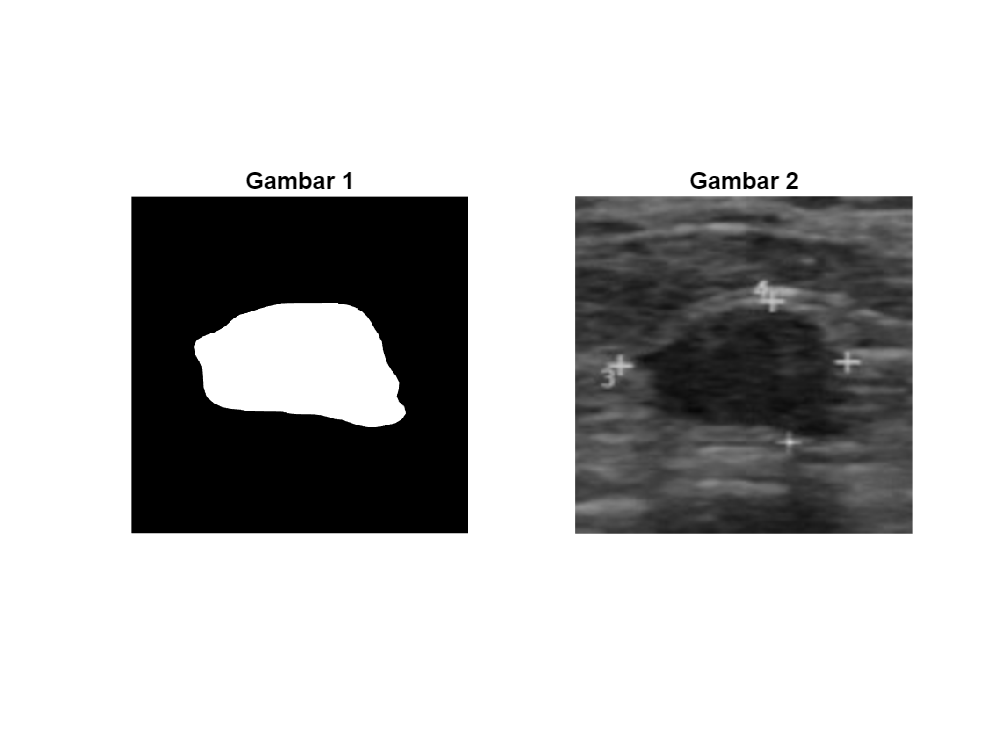

% Membaca gambar
img1 = imread(image1_path);
img2 = imread(image2_path);

% Menampilkan kedua gambar
figure;
subplot(1,2,1);
imshow(img1);
title('Gambar 1');

subplot(1,2,2);
imshow(img2);
title('Gambar 2');

% Informasi gambar 1
disp('--- Informasi Gambar 1 ---');

--- Informasi Gambar 1 ---


size_img1 = size(img1)

size_img1 =    384   384     3


class_img1 = class(img1)

class_img1 = 'uint8'

type_img1 = getImageType(img1)

type_img1 = 'RGB'


% Informasi gambar 2
disp('--- Informasi Gambar 2 ---');

--- Informasi Gambar 2 ---


size_img2 = size(img2)

size_img2 =    384   384


class_img2 = class(img2)

class_img2 = 'uint8'

type_img2 = getImageType(img2)

type_img2 = 'Grayscale'


function out = logicalToStr(val)
    if val
        out = 'YA';
    else
        out = 'TIDAK';
    end
end


% Bandingkan ukuran, tipe data, dan isi piksel
sameSize = isequal(size(img1), size(img2));
sameClass = strcmp(class(img1), class(img2));
samePixels = false;

if sameSize
    samePixels = isequal(img1, img2);
end

% Tampilkan hasil perbandingan
disp('--- Hasil Perbandingan ---');

--- Hasil Perbandingan ---


fprintf('Ukuran Sama       : %s\n', logicalToStr(sameSize));

Ukuran Sama       : TIDAK


fprintf('Tipe Data Sama    : %s\n', logicalToStr(sameClass));

Tipe Data Sama    : YA


fprintf('Isi Piksel Sama   : %s\n', logicalToStr(samePixels));

Isi Piksel Sama   : TIDAK


function tipe = getImageType(img)
    if islogical(img)
        tipe = 'Binary';
    elseif ndims(img) == 2
        tipe = 'Grayscale';
    elseif ndims(img) == 3 && size(img,3) == 3
        tipe = 'RGB';
    else
        tipe = 'Unknown';
    end
end

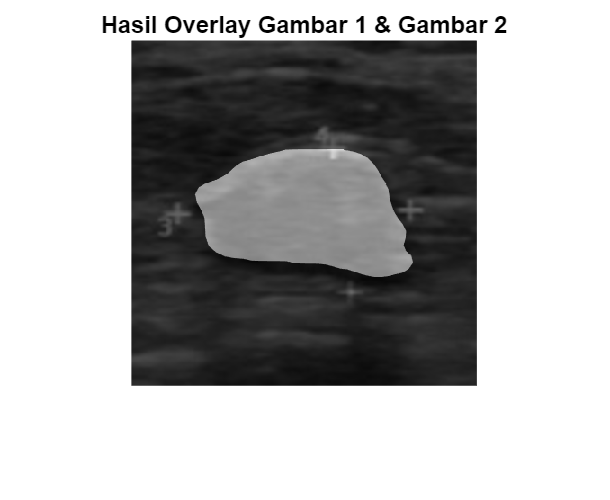

% Resize gambar ke ukuran yang sama (misalnya, samakan dengan gambar 1)
img2_resized = imresize(img2, [size(img1,1), size(img1,2)]);

% Overlay sederhana dengan rata-rata
overlay_img = uint8((double(img1) + double(img2_resized)) / 2);

% Tampilkan hasil overlay
figure;
imshow(overlay_img);
title('Hasil Overlay Gambar 1 & Gambar 2');